# *Problema di Galerkin*

Consideriamo un generico problema di reazione - diffusione - convezione nella forma: 


$$\begin{cases}
\nabla \cdot (\nu \nabla u) + \beta \nabla u + \sigma u = f & \text{in $\Omega$}\\
u = g_D &\text{ in $\partial \Omega$}\\
\frac{\partial u}{\partial n} = g_N &\text{ in $\partial \Omega$}
\end{cases}
$$


dove $\nu$ rappresenta il coefficiente convettivo, $\beta \;$il coefficiente diffusivo e $\sigma \;$il coefficiente reattivo; la prima condizione rappresenta una generica condizione imposta alla soluzione sul bordo del dominio (anche detta condizione di Dirichlet), mentre la seconda condizione, imposta alla derivata normale (uscente) della soluzione sul bordo del dominio è anche detta condizione di Neumann.

Volendo risolvere questo tipo di problema risulta necessario passare ad una formulazione agli elementi finiti (FEM), ovvero, passando per una formulazione variazionale e l'introduzione di una triangolazione, un problema di Galerkin.

La trattazione seguirà utilizzando un approccio didattico volto ad evidenziare il ragionamento per raggiungere questo tipo di soluzione, si procederà dapprima ad implementare una soluzione sfruttando come spazio dei polinomi $P_1$ e quindi si estenderà a $P_k$; si considereranno dapprima condizioni di Neumann e Dirichlet omogenee e poi si generalizzarà ed infine si procederà a calcolare l'errore.

Sfruttando il triangolatore bbtr30 in formato short si procederà dunque a risolvere il problema.

si osservino il comportamento del solutore del sistema lineare, il comportamento del

numero di condizionamento della matrice e il comportamento dell’errore.

Oss: nella definizione della mesh devo tenere conto che sto considerando delle condizioni al bordo di tipo Dirichlet e quindi dare in input al triangolatore l'informazione sui lati di bordo.

il comportamento del

numero di condizionamento della matrice e il comportamento dell’errore.

## Caso 1

Consideriamo ora il problema specifico: 


$$\begin{cases}
- \nu \Delta u = f & \text{in $\Omega$  }\\
u = 0 &\text{ in $\partial \Omega$}\\
\end{cases}
$$


a cui imponiamo una soluzione:


$$U\left(x,y\right)=16x\left(1-x\right)y\left(1-y\right)$$


che ci porta a considerare come forzante:

$f\left(x,y\right)=32\left(x\left(1-x\right)+y\left(1-y\right)\right)$.

Abbiamo dunque supposto $\nu =1$ e $\Omega =\left\lbrack 0,1\right\rbrack x\left\lbrack 0,1\right\rbrack$

currently inserted 2 triangles
currently inserted 3 triangles
currently inserted 6 triangles
currently inserted 8 triangles
currently inserted 9 triangles
currently inserted 13 triangles
currently inserted 14 triangles
currently inserted 16 triangles
currently inserted 21 triangles
currently inserted 25 triangles
currently inserted 30 triangles
currently inserted 36 triangles
currently inserted 42 triangles
currently inserted 54 triangles
currently inserted 68 triangles
currently inserted 73 triangles
currently inserted 79 triangles
currently inserted 96 triangles
currently inserted 101 triangles
currently inserted 107 triangles
currently inserted 124 triangles
currently inserted 133 triangles
currently inserted 144 triangles
currently inserted 151 triangles
currently inserted 159 triangles
currently inserted 181 triangles
currently inserted 187 triangles
currently inserted 195 triangles
currently inserted 217 triangles
currently inserted 227 triangles
currently inserted 233 triangles


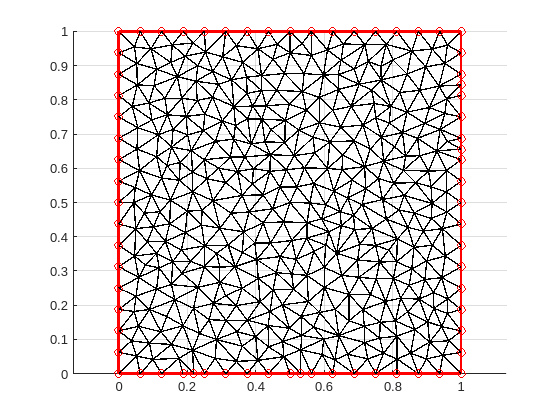

clc; clear all; close all;
%triangolazione
geom = mesha(0.002);

Tramite la funzione mesh, che prende in input il massimo valore di area da utilizzare per il calcolo della mesh di $\Omega =\left\lbrack 0,1\right\rbrack x\left\lbrack 0,1\right\rbrack$, abbiamo ottenuto una triangolazione che rappresenta in rosso i lati di Dirichlet ed in blu quelli di Neumann. 

La funzione restituisce un oggetto "geom" contenente tutte le informazioni utili sulla nostra triangolazione.

Procediamo dunque ad estrarre da geom le informazioni su

- **Ndof **Gradi di libertà, cioè il numero dei nodi, esclusi quelli di Dirichlet (che hanno gdl = 0);

- **XY** matrice 2X2 contenente le coordinate dei punti che compongolo la triangolazione;

- **T **vettore contenente gli indici della triangolazione;

- PIV

Procedo dunque definendo i dati caratteristici del problema, quindi i vari coefficienti, la forzante, le eventuale condizioni di Neumann o Dirichlet, la soluzione esatta.

A questo punto alloco in memoria una matrice sparsa A del problema di Galerkin, un vettore b sparso dei termini noti del problema e u soluzione discretizzata.

%DATI TRIANGOLAZIONE
Ndof = geom.Nobj.N_node-size(geom.piv.Di,1); %numero GDL
N_ele = geom.Nobj.N_ele; %numero di triangoli
NNe = size(geom.piv.Ne,1); % numero nodi Neumann
NDi = size(geom.piv.Di(:,1),1); %numero nodi Dirichlet
XY = geom.obj.P; %coordinate
T = geom.obj.T; %indici vettori
PIV = geom.piv.piv; %pivot

%PARAMETRI DEL PROBLEMA
ni = 1;  %coefficiente diffusivo
beta = [0 0]; %coefficiente convettivo
sigma = 0; %coefficiente reattivo
f = @(x,y) 32*(x.*(1-x) + y.*(1-y)); %forzante
gD = @(x,y) 0; %condizione di Dirichlet
gN = @(x,y) 0;  %condizione di Neumann  
U = @(x,y) 16*x.*(1-x).*y.*(1-y); %soluzione esatta


%ALLOCAZIONE VARIABILI
A = spalloc(Ndof,Ndof, 10*Ndof); %coefficienti forma A
AD = spalloc(Ndof,NDi, 10*Ndof); %coefficienti condizione di Dirichlet
uD = zeros(NDi, 1);  % per la condizione di Dirichelt
u = zeros(Ndof, 1); %soluzione approssimata
b = zeros(Ndof,1); %coefficienti termine noto
dx = zeros(3,1);
dy = zeros(3,1);

Faccio partire il metodo, ciclando su tutti i triangoli della triangolazione

- Calcolo (con metodo dei trapezi nel caso $P_1$, più in generale con nodi di quadratura) i coefficienti della forma A;

- Calcolo analogamente i coefficienti della forma b;

La soluzione ottenuta risolvendo questo problema corrisponderà alla soluzione omogenea del problema, intendendo con soluzione omogenea la soluzione del problema a cui vengono associate condizioni di Neumann e Dirichlet al bordo omogenee.

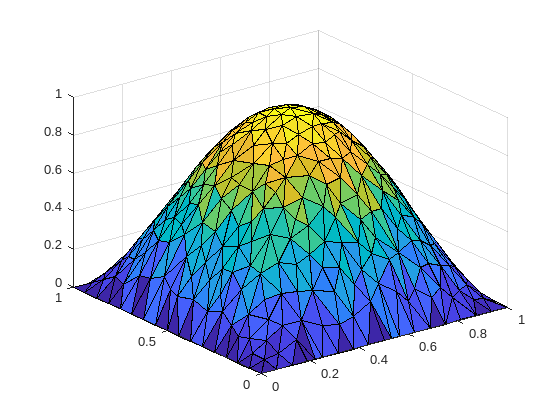

%soluzione omogenea
for e =  1 : N_ele
    %x
    dx(1) = XY(T(e,3),1) - XY(T(e,2),1);
    dx(2) = XY(T(e,1),1) - XY(T(e,3),1);
    dx(3) = XY(T(e,2),1) - XY(T(e,1),1);

    %y
    dy(1) = XY(T(e,2),2) - XY(T(e,3),2);
    dy(2) = XY(T(e,3),2) - XY(T(e,1),2);
    dy(3) = XY(T(e,1),2) - XY(T(e,2),2);

    tri = geom.support.TInfo(e);

    x_G = tri.CG(1); %x del baricentro
    y_G = tri.CG(2); %y del baricentro

    %calcolo l'area
    E = tri.Area;

    for j = 1 : 3
        jj = PIV(T(e,j));
        if jj>0
            for k = 1 : 3
                kk = PIV(T(e,k)); 
                if kk>0
                    %coefficienti forma A 
                    %metodo con P1
                    A(jj,kk) = A(jj,kk) + ni*((dy(k)*dy(j) + dx(j)*dx(k))/(4*E))+ (beta(1)*dy(k) + beta(2)*dx(k))/6 + sigma*E*(1+(j==k))/12;
                else
                    %coefficienti forma A con condizioni di Dirichlet
                    %metodo con P1
                    AD(jj,-kk) = AD(jj,-kk) + ni*((dy(k)*dy(j) + dx(j)*dx(k))/(4*E))+ (beta(1)*dy(k) + beta(2)*dx(k))/6 + sigma*E*(1+(j==k))/12;
                end
            end
            %coefficienti termine noto
            b(jj) = b(jj) + f(x_G,y_G)*E/3;
        end
    end
end

%soluzione con Dirichlet
for i =1:NDi
    ii = geom.piv.Di(i,1);
    uD(i) = gD(XY(ii,1), XY(ii,2));
end

%termine noto Neumann
for e = 1:NNe
    l = geom.piv.Ne(e);

    ib = geom.obj.E(l,1);  %indice nodo di inizio lato
    ie = geom.obj.E(l,2);  %indice nodo di fine lato

    x_b = XY(ib,1);
    y_b = XY(ib,2);
    x_e = XY(ie,1);
    y_e = XY(ie,2);

    iib = PIV(ib);  %gradi di liberta nodo inizio
    iie = PIV(ie);  %gradi di liberta nodo fine

    lun = sqrt((x_b-x_e).^2+(y_b-y_e).^2);
    if iib>0
        b(iib) = b(iib) + (gN(x_b,y_b)/3+gN(x_e,y_e)/6) *lun;
    end
    if iie>0
        b(iie) = b(iie) + (gN(x_b,y_b)+gN(x_e,y_e))/6*lun;
    end
end

%calcolo il termine noto complessivo
b = b - AD*uD;

uO = A\b;

for i = 1 : geom.Nobj.N_node
    ii = PIV(i);
    if ii>0
        u(i) = uO(ii);
    else
        u(i) = uD(-ii);
    end
end

%soluzione approssimata
figure
trisurf(T,XY(:,1),XY(:,2), u)  

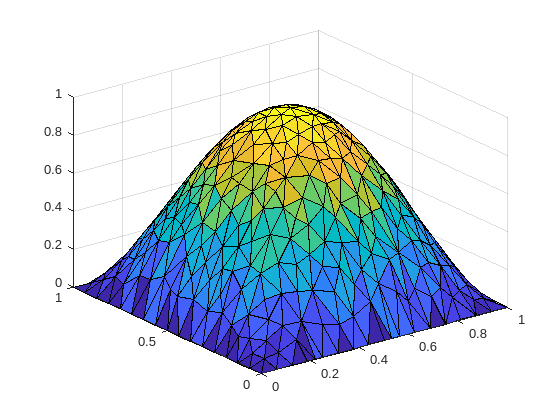

%soluzione esatta
figure
trisurf(T, XY(:,1),XY(:,2), U(XY(:,1),XY(:,2)))

%errore di approssimazione
err = norm(U(XY(:,1),XY(:,2))-u)

err = 0.0215

%condizionamento
condest(A)

ans = 276.5225

currently inserted 2 triangles
currently inserted 3 triangles
currently inserted 6 triangles
currently inserted 8 triangles
currently inserted 9 triangles
currently inserted 13 triangles
currently inserted 14 triangles
currently inserted 16 triangles
currently inserted 21 triangles
currently inserted 25 triangles
currently inserted 30 triangles
currently inserted 33 triangles
currently inserted 36 triangles
currently inserted 46 triangles
currently inserted 56 triangles
currently inserted 64 triangles
currently inserted 72 triangles
currently inserted 76 triangles


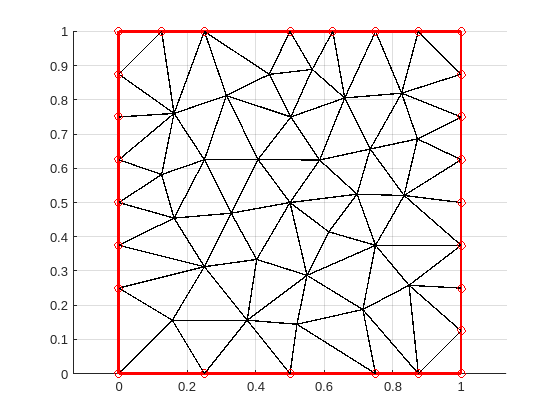




%considero ora le considizioni di Dirichlet al bordo
%devo scegliere come gD una funzione che ha laplaciano nullo altrimenti
%devo aggiungerlo come forzante


clc; clear all; close all;
%triangolazione
geom = mesha(0.02);

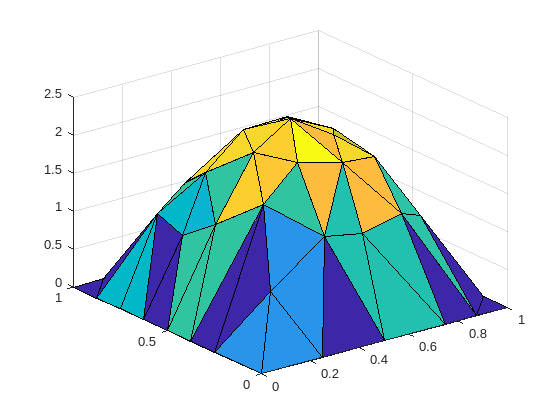

%DATI TRIANGOLAZIONE
Ndof = geom.Nobj.N_node-size(geom.piv.Di,1); %numero GDL
N_ele = geom.Nobj.N_ele; %numero di triangoli
NNe = size(geom.piv.Ne,1); % numero nodi Neumann
NDi = size(geom.piv.Di(:,1),1); %numero nodi Dirichlet
XY = geom.obj.P; %coordinate
T = geom.obj.T; %indici vettori
PIV = geom.piv.piv; %pivot

%PARAMETRI DEL PROBLEMA
ni =@(x,y) ones(size(x));  %coefficiente diffusivo
beta =@(x,y) zeros(2,1); %coefficiente convettivo
sigma =@(x,y) zeros(size(x)); %coefficiente reattivo
f = @(x,y) 32*(x.*(1-x) + y.*(1-y)); %forzante
gD = @(x,y) 0; %condizione di Dirichlet
gN = @(x,y) 0;  %condizione di Neumann  
U = @(x,y) 16*x.*(1-x).*y.*(1-y); %soluzione esatta


% %ALLOCAZIONE VARIABILI
A = spalloc(Ndof,Ndof, 10*Ndof); %coefficienti forma A
AD = spalloc(Ndof,NDi, 10*Ndof); %coefficienti condizione di Dirichlet
uD = zeros(NDi, 1);  % per la condizione di Dirichelt
u = zeros(Ndof, 1); %soluzione approssimata
b = zeros(Ndof,1); %coefficienti termine noto
dx = zeros(3,1);
dy = zeros(3,1);

% X = zeros(31,1);
% H = zeros(31,1);
% ERR = zeros(31,1);

[xhat,yhat, zhat,omega] = int_nodes_weights(5);
Nq = size(xhat,2);

% phi= zeros(3,8,3);
dphi = [1 0; 0 1;-1 -1]';
%t =@(x,y,z) [x;y;z];
phi = [xhat;yhat; zhat];

area = 0.02;

    
  
  

hA = zeros(Ndof,1);

%soluzione omogenea
for e =  1 : N_ele
    %x
    dx(1) = XY(T(e,3),1) - XY(T(e,2),1);
    dx(2) = XY(T(e,1),1) - XY(T(e,3),1);
    dx(3) = XY(T(e,2),1) - XY(T(e,1),1);

    %y
    dy(1) = XY(T(e,2),2) - XY(T(e,3),2);
    dy(2) = XY(T(e,3),2) - XY(T(e,1),2);
    dy(3) = XY(T(e,1),2) - XY(T(e,2),2);

    tri = geom.support.TInfo(e);

    x_G = tri.CG(1); %x del baricentro
    y_G = tri.CG(2); %y del baricentro

    %calcolo l'area
    E = tri.Area;
    hA(e) = E;
    B = [dx(2) -dx(1); -dy(2) dx(1)];
    B_mt = [dy(1) dy(2); dx(1) dx(2)]*1/(2*E);
    
    for j = 1 : 3
        jj = PIV(T(e,j));
        if jj>0
            for k = 1 : 3
                kk = PIV(T(e,k));
                if kk>0
                    %coefficienti forma A
                    %metodo con P1
                    for q = 1:Nq
                        A(jj,kk) = A(jj,kk) + 2*E*(omega(q)*ni(xhat(q), yhat(q))'*dphi(:,k)'*(B_mt)'*B_mt*dphi(:,j)+omega(q)*beta(xhat(q), yhat(q))'*B_mt*(dphi(:,k))*phi(j,q)+ omega(q)*sigma(xhat(q),yhat(q))'*phi(k,q)*phi(j,q));
                    end
                    % A(jj,kk) = A(jj,kk) + ni*((dy(k)*dy(j) + dx(j)*dx(k))/(4*E))+ (beta(1)*dy(k) + beta(2)*dx(k))/6 + sigma*E*(1+(j==k))/12;
                else
                    %coefficienti forma A con condizioni di Dirichlet
                    %metodo con P1
                    l = 0;
                    %%CORREGGI FORMULA SBAGLIATA
                    for q = 1:Nq
                        AD(jj,-kk) = AD(jj,-kk) + 2*E*(omega(q)*ni(xhat(q), yhat(q))'*dphi(:,k)'*(B_mt)'*B_mt*dphi(:,j)+omega(q)*beta(xhat(q), yhat(q))'*B_mt*(dphi(:,k))*phi(j,q)+ omega(q)*sigma(xhat(q),yhat(q))'*phi(k,q)*phi(j,q));
                     % AD(jj,-kk) = AD(jj,-kk) + ni*((dy(k)*dy(j) + dx(j)*dx(k))/(4*E))+ (beta(1)*dy(k) + beta(2)*dx(k))/6 + sigma*E*(1+(j==k))/12;
               
                    end
                end

            end
            %coefficienti termine noto
            %b(jj) = b(jj) + f(x_G,y_G)*E/3;
            b(jj) = b(jj) + omega*f(xhat,yhat)'*2*E;
        end
    end
end

%soluzione con Dirichlet
for i =1:NDi
    ii = geom.piv.Di(i,1);
    uD(i) = gD(XY(ii,1), XY(ii,2));
end


% hl = zeros(NNe,1);
%termine noto Neumann
for e = 1:NNe
    l = geom.piv.Ne(e);

    ib = geom.obj.E(l,1);  %indice nodo di inizio lato
    ie = geom.obj.E(l,2);  %indice nodo di fine lato

    x_b = XY(ib,1);
    y_b = XY(ib,2);
    x_e = XY(ie,1);
    y_e = XY(ie,2);

    iib = PIV(ib);  %gradi di liberta nodo inizio
    iie = PIV(ie);  %gradi di liberta nodo fine

    lun = sqrt((x_b-x_e).^2+(y_b-y_e).^2);

    % hl(e) = lun;
    if iib>0
        b(iib) = b(iib) + (gN(x_b,y_b)/3+gN(x_e,y_e)/6) *lun;
    end
    if iie>0
        b(iie) = b(iie) + (gN(x_b,y_b)+gN(x_e,y_e))/6*lun;
    end
end

%calcolo il termine noto complessivo
b = b - AD*uD;

uO = A\b;

for i = 1 : geom.Nobj.N_node
    ii = PIV(i);
    if ii>0
        u(i) = uO(ii);
    else
        u(i) = uD(-ii);
    end
end

%soluzione approssimata
figure
trisurf(T,XY(:,1),XY(:,2), u)

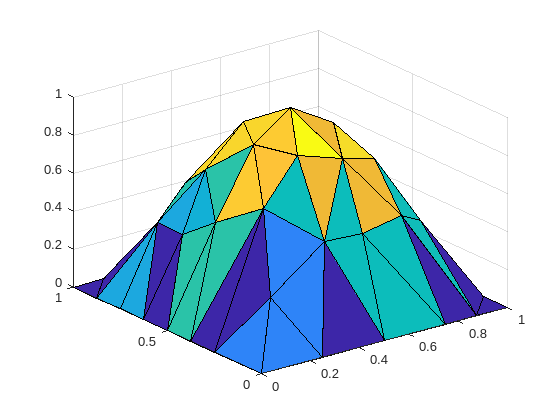

%soluzione esatta
 figure
 trisurf(T, XY(:,1),XY(:,2), U(XY(:,1),XY(:,2)))


 %%TODO
 
 %Calcolo dell'errore
errL2 = 0;
errH1 = 0;
dU = @(x,y) [16*(1-2*x)*y*(1-y);16*(1-2*y)*x*(1-2*x)];
for e = 1: N_ele
     %x
    dx(1) = XY(T(e,3),1) - XY(T(e,2),1);
    dx(2) = XY(T(e,1),1) - XY(T(e,3),1);
    dx(3) = XY(T(e,2),1) - XY(T(e,1),1);

    %y
    dy(1) = XY(T(e,2),2) - XY(T(e,3),2);
    dy(2) = XY(T(e,3),2) - XY(T(e,1),2);
    dy(3) = XY(T(e,1),2) - XY(T(e,2),2);
    
    %E = tri.Area;
    %h(e) = E;
    %B = [dx(2) -dx(1); -dy(2) dx(1)];
    B_mt = [dy(1) dy(2); dx(1) dx(2)]*1/(2*E);

    s = 0 ;
    t = zeros(2,1);
    E = geom.support.TInfo(e).Area;
    for q = 1: Nq
        for k = 1 : 3
            kk = PIV(T(e,k));
            if kk>0  
                s = s + u(k)*phi(k,q);          
                t = t + u(k)*dphi(:,k);
            end
        end
        errL2 = errL2 + omega(q)*(U(xhat(q), yhat(q))-s)^2*2*E;
        errH1 = errH1 + omega(q)*(dU(xhat(q), yhat(q))-B_mt*t)'*(dU(xhat(q), yhat(q))-B_mt*t)*2*E;

    end   
end
errL2;
errH1;
errLinf = norm(U(XY(:,1),XY(:,2))-u, inf); 
 
%h
% h = max(hl);

Area

L2 -> 1

H1 ->0.5

L inf -> 1

cond = -1;

Lato

L2 -> 2

H1 ->1

L inf -> 2

cond = -2;

h = Ndof^(-0.5);
pL2 = polyfit(log(h), log(errL2),1);

pL2(1)

ans = 0.7218


pH1 = polyfit(log(h), log(errH1),1);

pH1(1)

ans = -1.2232


pLinf = polyfit(log(h), log(errLinf),1);

pLinf(1)

ans = -0.1850

hAmax = max(hA);

pAL2 = polyfit(log(hAmax), log(errL2),1);

pAL2(1)

ans = 0.3056


pAH1 = polyfit(log(hAmax), log(errH1),1);

pAH1(1)

ans = -0.5178


pALinf = polyfit(log(hAmax), log(errLinf),1);

pALinf(1)

ans = -0.0783





% errL2 = 0;
% for e = 1:N_ele
%     for q = 1: length(omega)
%         for k = 1: NNE
%             %AGGIUSTA
%             err = u(k)*phi_hat(xhat, yhat);
%         end
%         E = geom.support.TInfo(e).Area;
%         errL2 = errL2+omega(q)*2*E*(U(xhat(q),yhat(q))-u(e))^2;
%     end
% end




% norm(U(XY(:,1),XY(:,2))-u)
% erinf =norm(U(XY(:,1),XY(:,2))-u, inf);
% h^2;
% p = polyfit(log(h), log(err),1);
% p(1)
% X(s+1) = p(1);
% H(s+1) = h;
% ERR(s+1) = err;
%condizionamento
condest(A)

ans = 24.8886

L'area scala come l'area scala come A^(k/2) seminorma di u_k+1

(RICORDATI di creare una matrice 3D per metterci il gradietne di phi ecc)